imds = imageDatastore('kitchen','IncludeSubfolders',true,'LabelSource','foldernames');
tbl = countEachLabel(imds)

tbl = 5×2 table
     Label      Count
    ________    _____

    Bottle       10  
    Fork         10  
    Peeler       10  
    Scissors     10  
    mug          10  


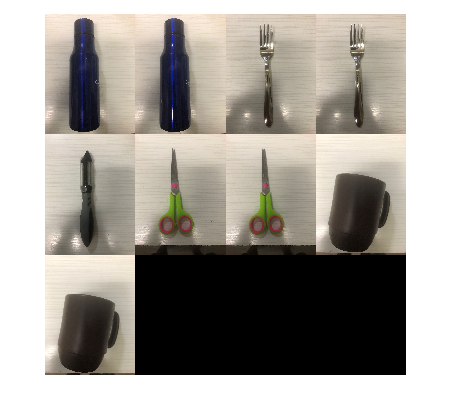

figure
montage(imds.Files(1:6:end))

[trainingSet, validationSet] = splitEachLabel(imds, 0.6, 'randomize');
bag = bagOfFeatures(trainingSet);

Creating Bag-Of-Features.
-------------------------
* Image category 1: Bottle
* Image category 2: Fork
* Image category 3: Peeler
* Image category 4: Scissors
* Image category 5: mug
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 30 images...done. Extracted 5898240 features.

* Keeping 80 percent of the strongest features from each category.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 4718590
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clustering...completed 24/100 iterations (~8.30 seconds/iteration)...converged in 24 iterations.

* Finished creating Bag-Of-Features



img = readimage(imds, 1);
featureVector = encode(bag, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


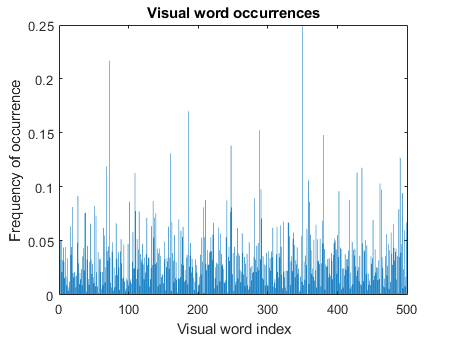

% Plot the histogram of visual word occurrences
figure
bar(featureVector)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')

categoryClassifier = trainImageCategoryClassifier(trainingSet, bag);

Training an image category classifier for 5 categories.
--------------------------------------------------------
* Category 1: Bottle
* Category 2: Fork
* Category 3: Peeler
* Category 4: Scissors
* Category 5: mug

* Encoding features for 30 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.



confMatrix = evaluate(categoryClassifier, trainingSet);

Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: Bottle
* Category 2: Fork
* Category 3: Peeler
* Category 4: Scissors
* Category 5: mug

* Evaluating 30 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                              PREDICTED
KNOWN       | Bottle   Fork   Peeler   Scissors   mug    
---------------------------------------------------------
Bottle      | 1.00     0.00   0.00     0.00       0.00   
Fork        | 0.00     1.00   0.00     0.00       0.00   
Peeler      | 0.00     0.00   1.00     0.00       0.00   
Scissors    | 0.00     0.00   0.00     1.00       0.00   
mug         | 0.00     0.00   0.00     0.00       1.00   

* Average Accuracy is 1.00.



confMatrix = evaluate(categoryClassifier, validationSet);

Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: Bottle
* Category 2: Fork
* Category 3: Peeler
* Category 4: Scissors
* Category 5: mug

* Evaluating 20 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                              PREDICTED
KNOWN       | Bottle   Fork   Peeler   Scissors   mug    
---------------------------------------------------------
Bottle      | 1.00     0.00   0.00     0.00       0.00   
Fork        | 0.00     1.00   0.00     0.00       0.00   
Peeler      | 0.00     0.00   1.00     0.00       0.00   
Scissors    | 0.00     0.00   0.00     1.00       0.00   
mug         | 0.00     0.00   0.00     0.00       1.00   

* Average Accuracy is 1.00.



% Compute average accuracy
mean(diag(confMatrix))

ans = 1

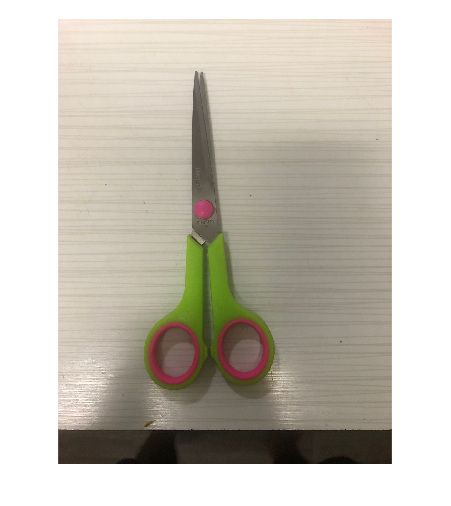


img = imread(fullfile('kitchen','Scissors','Scissors.jpeg'));
figure
imshow(img)

[labelIdx, scores] = predict(categoryClassifier, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.



% Display the string label
categoryClassifier.Labels(labelIdx)

ans = 1×1 cell array
    {'Scissors'}
